# Experimento das rodas - Selecionado

### Baseado no bode e no experimento exp2_rodas 

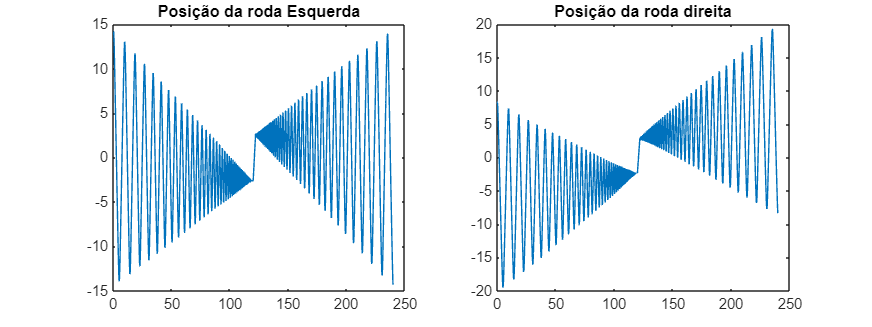

clear
load("exp_rodas.mat")

ti = t_trig;
f = freq;
ts = 0.01;
t_uni = 0:ts:length(u)*ts-ts;

figure
pos = get(gcf, 'Position'); set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]); clear pos;

subplot(1,2,1)
plot(t, yl); title("Posição da roda Esquerda")
subplot(1,2,2)
plot(t, yr); title("Posição da roda direita")

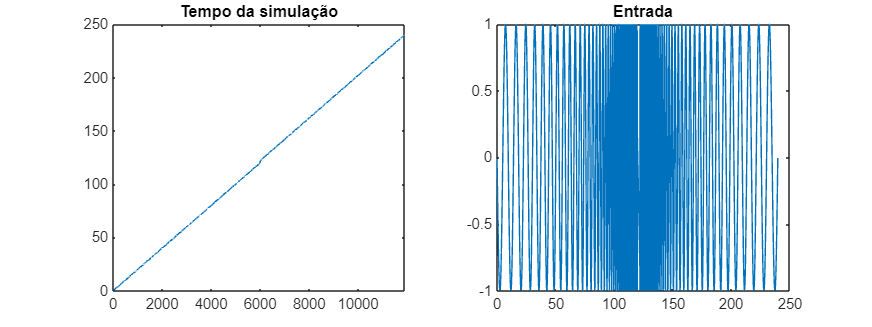

figure
pos = get(gcf, 'Position'); set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]); clear pos;

subplot(1,2,1)
plot(t); title("Tempo da simulação")
subplot(1,2,2)
plot(t, u); title("Entrada")

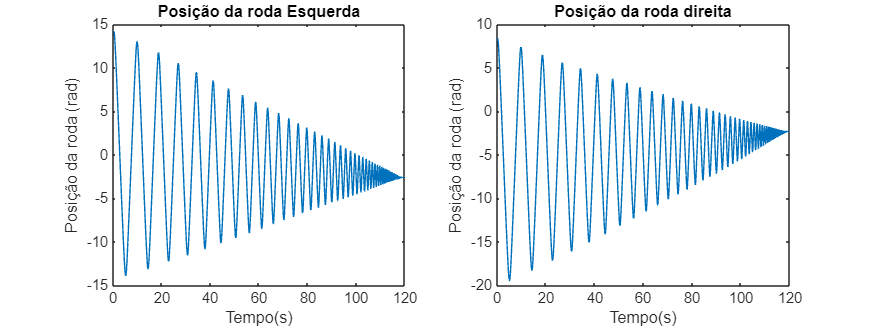

idx = t>0 & t<120;
limx = [0,120];
% idx = t>122 & t<240;
% idx = t>0 & t<240;

figure
pos = get(gcf, 'Position'); set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]); clear pos;

subplot(1,2,1); 
plot(t, yl)
title("Posição da roda Esquerda"); xlabel('Tempo(s)'); ylabel('Posição da roda (rad)'); xlim(limx);

subplot(1,2,2)
plot(t, yr)
title("Posição da roda direita"); xlabel('Tempo(s)'); ylabel('Posição da roda (rad)'); xlim(limx);

figure
dados = iddata(yl(idx), u(idx), ts);
G = tfest(dados, 1, 0)

G =
 
  From input "u1" to output "y1":
      14.69
  -------------
  s + 4.026e-10
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "dados".
Fit to estimation data: 74.79%                    
FPE: 1.894, MSE: 1.893                            
 
Model Properties


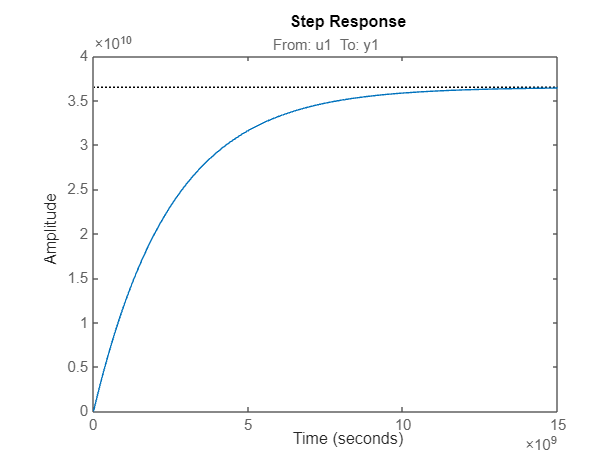

step(G)

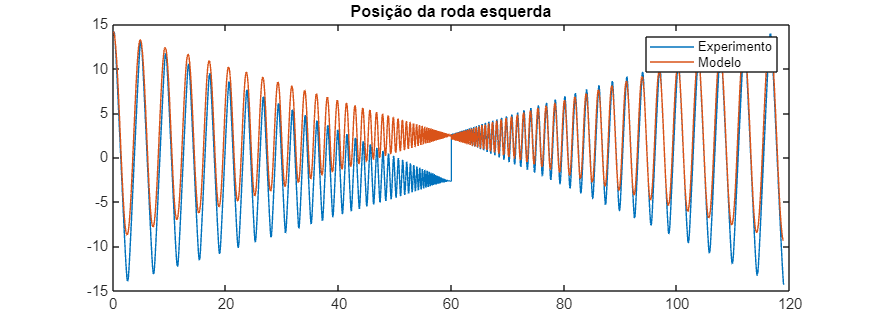

% tt = 0:ts:length(u(idx))*ts-ts;

y = lsim(G, u, t_uni);
figure
pos = get(gcf, 'Position'); set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]); clear pos;

plot(t_uni, yl)
title("Posição da roda esquerda"); hold on;
plot(t_uni, y + yl(1))
xlim(limx); legend("Experimento", "Modelo");

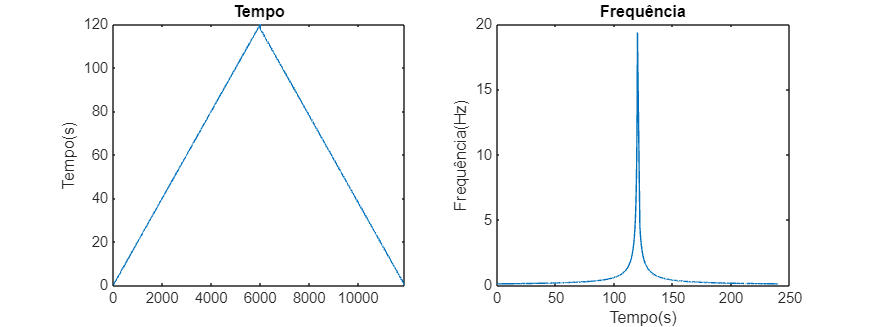

figure
pos = get(gcf, 'Position'); set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]); clear pos

subplot(1,2,1)
plot(ti)
title('Tempo'); ylabel('Tempo(s)')
subplot(1,2,2) 
plot(t, freq)
title('Frequência'); xlabel('Tempo(s)'); ylabel('Frequência(Hz)')

t1 = t(idx);
u1 = u(idx);
yl1 = yl(idx);
yr1 = yr(idx);
freq1 = freq(idx);

max(u1)

ans = 1

max(lvel)

ans = 6.9006

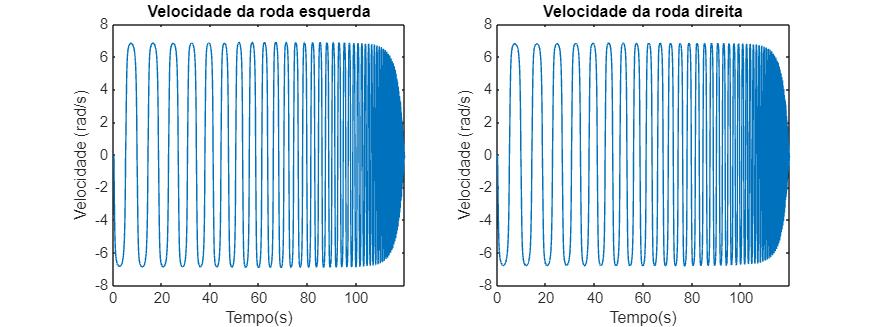


figure
pos = get(gcf, 'Position'); set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]); clear pos

subplot(1,2,1)
plot(t, dyl)
title("Velocidade da roda esquerda"); xlabel('Tempo(s)'); ylabel('Velocidade (rad/s)')

subplot(1,2,2)
plot(t, dyr)
title("Velocidade da roda direita"); xlabel('Tempo(s)'); ylabel('Velocidade (rad/s)')

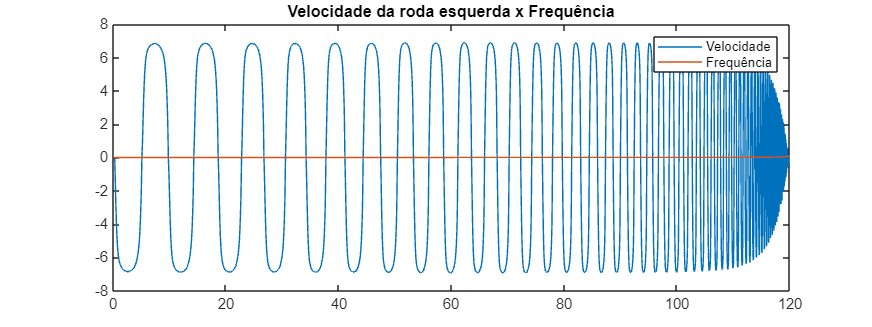

figure
pos = get(gcf, 'Position'); set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]); clear pos

x = [t1(1) t1(end)];

plot(t, dyl/max(dyl))
title("Velocidade da roda esquerda x Frequência"); hold on
plot(t, freq1/max(freq1)) 
legend(["Velocidade" "Frequência"])

idx = t>0 & t<240;
t1 = t(idx);
u1 = u(idx);
yl1 = yl(idx);
yr1 = yr(idx);

max(lvel) / max(u1)

ans = 66.1377

left = iddata(lvel, u1, ts);
% G_l = tfest(left, 1, 0);
s = tf("s");
K = max(lvel) / max(u1);
tau_p = 1/18;

### Valores Ideais:

- K = -1.91;

- $\tau$ = 0.05.

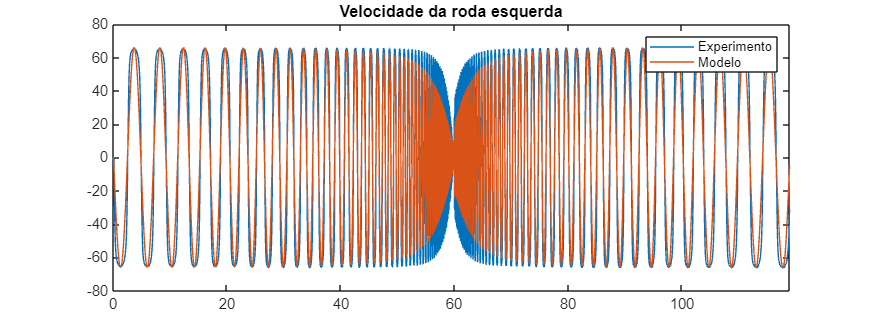

G_l = K*1/(tau_p*s+1);

t_uni = 0:ts:length(u1)*ts-ts;
idx = (1:length(t_uni));

y = lsim(G_l, u1, t_uni);
figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

plot(t_uni(idx), lvel(idx))
title("Velocidade da roda esquerda")
hold on
plot(t_uni(idx), y(idx))
xlim([t_uni(idx(1)) t_uni(idx(end))])
legend("Experimento", "Modelo")

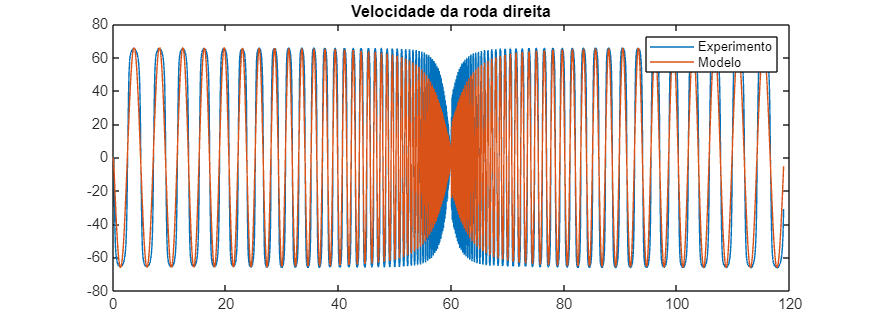

rigth = iddata(rvel, u1, ts);
G_r = tfest(rigth, 2, 0);
G_r = K*1/(tau_p*s+1);

y = lsim(G_r, u1, t_uni);
figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

plot(t_uni, lvel)
title("Velocidade da roda direita")
hold on
plot(t_uni, y)
legend("Experimento", "Modelo")

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

semilogx(freq_rad, Declvel)

Unrecognized function or variable 'freq_rad'.

title("Velocidade da roda esquerda")
xlabel("Frequência (rad)")
ylabel("Ganho(DeciBel)")

W = linspace(min(freq_rad), max(freq_rad), length(freq_rad));
[MAG,PHASE,W] = bode(G_l, W);
MAG = squeeze(MAG);
MAG1 = 20*log10(MAG);

G_l = G_l * tf(1, [1/(18.5*3) 1])
% G_l = tf(K, [1/20 1])
[MAG,PHASE,W] = bode(G_l, W);
MAG = squeeze(MAG);
MAG2 = 20*log10(MAG);


figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

subplot(1,2,1)
semilogx(freq_rad, Declvel)
hold on
semilogx(W,MAG1)
xlim([min(freq_rad), max(freq_rad)])
title("Bode de G 1º ordem")

subplot(1,2,2)
semilogx(freq_rad, Declvel)
hold on
semilogx(W,MAG2)
xlim([min(freq_rad), max(freq_rad)])
title("Bode de G 2º ordem")

G_r
zpk(G_r)
K_rodas = ans.K
tau = -1/ans.P{1}